# **RT-QIBC cell analysis**

**FarRed1: Cdt1 IF stain**

**FarRed2: EdU incorporation**

**YFP2: Geminin IF stain**

**POI(:,3): CRL4Cdt2 activation**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';

%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
    %      'siCtrl 20 no dox',2,2,2,[0 0 0]; %1
    'siCtrl 20 no dox',2:3,2,1:9,[0 0 0]; %1
    'siGMNN 20 no dox',4,2,1:9,[0 0 0]; %1
    'siGMNN 1 no dox',5:6,2,1:9,[0 0 0]; %1
    'siGMNN 0.1 no dox',7,2,1:9,[0 0 0]; %1
    
    'siCtrl 20 dox',2:3,3:11,1:9,[0 0 0]; %1
    'siGMNN 20 dox',4,3:11,1:9,[0 0 0]; %1
    'siGMNN 1 dox',5:6,3:10,1:9,[0 0 0]; %1
    'siGMNN 0.1 dox',7,3:11,1:9,[0 0 0]; %1
    
    };


load([dataDir filesep 'C224_data.mat'],'S');

% S = loadData(conditions, dataDir);

framesPerHr = 60/12;
frameDrugAdded = 74;
frameEdU = 0;
timeStart = .6;
folding =5;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames;
xTime = (xFrames-1)./framesPerHr;

POI_time = arrayfun(@(x) (numFrames - x.POI)/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};

**Set thresholds**

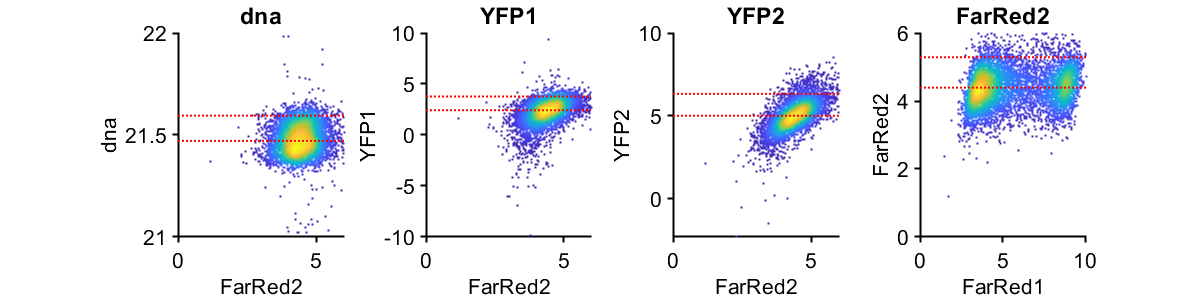

%% Set gates G1
cond=1;
gate = struct();
gates = {'dna','YFP1','YFP2','FarRed2'};
plotting = {'FarRed2','FarRed2','FarRed2','FarRed1'};
prctiles = {[50 95], [50 95],[50 95],[50 95],[50 95]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = isnan(S(cond).POI(:,2)) & isnan(S(cond).POI(:,3)) & ...
        S(cond).dna < 2^22 & S(cond).dna > 2^21 & S(cond).FarRed2 < 2^6;
    
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(real(log2(xdata)),real(log2(ydata)));
    hline( log2(gate.([gates{i} '_G1'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

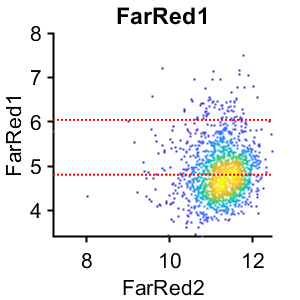


gates = {'FarRed1'};
plotting = {'FarRed2'};
prctiles = {[50 95]};
figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,3) <= 3 & S(cond).POI_time(:,3) > 2 & S(cond).FarRed2 > 2^6 ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_S']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_S'])))
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

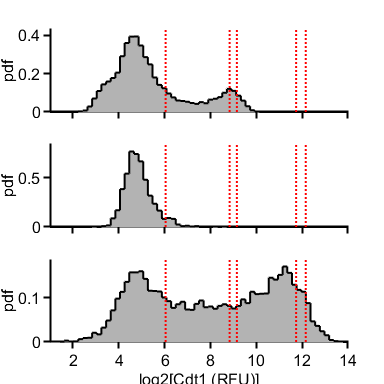

f = figure('units','inches','pos',[0 0 4 4]);
data = {};
cond = 1;
inds = S(cond).FarRed1 > 2^0 & S(cond).FarRed1 < 2^15;
data =[ data real(log2(S(cond).FarRed1(inds)))];

conds=[1 5];
for i=1:length(conds)
    condition = conds(i);
    inds = S(condition).POI_time(:,3) < 3 & S(condition).POI_time(:,3) > 2  &  S(condition).FarRed1 > 2^0 & S(condition).FarRed1 < 2^15;
    data = [data real(log2(S(condition).FarRed1(inds)))];
end
hold on
nhist(data,'samebins','pdf','noerror','separate','minx',0,'maxx',15,'LineWidth',1.5);
trunc_thresh = log2(gate.FarRed1_S(2));
%endo_thresh = prctile(data{1}(data{1} > trunc_thresh),75)
[p, xi] = ksdensity(data{1});
trunc_xi = xi(xi > trunc_thresh);
trunc_p = p(xi > trunc_thresh);
[~,i] = max(trunc_p);
endo_max = trunc_xi(i);
trun_data = data{1}(data{1} > endo_max);
endo_thresh = prctile(trun_data,(75 - 50)*2);
% xvals = linspace(2,14,100);
% GMModel = fitgmdist(data{1},2);
% [~, comp] = max(GMModel.mu);
% endo_thresh = norminv(.75) * GMModel.Sigma(comp) + GMModel.mu(comp);
endo_mid = 2.^endo_thresh;

% set(gca,'FontSize',16)
ax = get(f,'children');
for i = 1:length(ax)
    axes(ax(i))
    xlim([1 14])
    vline(log2(gate.FarRed1_S(2)))
%     vline(trunc_thresh)
    vline(endo_thresh)
    vline(endo_max)
    vline(log2([6 8] * 2^endo_thresh))
    if i ~= 1
        set(gca,'xticklabel',{[]})
        %         set(gca,'xlabel','log2(Cdt1) (AU)')
    else
        xlabel('log2[Cdt1 (RFU)]');
    end
end
% plot(xvals,GMModel.ComponentProportion(1) * normpdf(xvals,GMModel.mu(1),GMModel.Sigma(1)));
% plot(xvals,GMModel.ComponentProportion(2) * normpdf(xvals,GMModel.mu(2),GMModel.Sigma(2)));
% plot(xvals,pdf(GMModel, xvals'),'r','LineWidth',1.5)
print_pdf([pwd() '\Figs\cdt1hist.pdf'])

**compare**

rng(1)
endo_mid = 2.^endo_max;

gateVals = {{},{'FarRed1'}};
% rangeVals = {{[]},{[endo_mid*6 endo_mid*8]}};
rangeVals = {{[]},{[2^11 Inf]}};

conds=[1 5*ones(1,length(gateVals)-1)];
colors = [0 113 188; 193 39 45]/255;

poiAligned=3;
f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
hold on

colorval = [1 2];
pattern = {'-','-'};
subsamplecells = [5700 2000];
% range = 0:1/framesPerHr:7;
alphas = [.05 .1];
for i=1:length(conds)
    ind=~isnan(S(conds(i)).POI(:,poiAligned))& ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i}) & S(conds(i)).POI_time(:,poiAligned) <= 5;
    
    xdata = S(conds(i)).POI_time(ind,poiAligned);
    ydata = [];
    ydata(:, 1) = (S(conds(i)).dna(ind))/gate.dna_G1(1);
    ydata(:, 2) = (S(conds(i)).YFP2(ind));
    ydata(:, 3) = (S(conds(i)).FarRed2(ind) - gate.FarRed2_G1(1)) ;
    
    
    range = [unique(xdata); Inf];
    threshs ={{(gate.dna_G1(2)), -1}, {(gate.YFP2_G1(2)), 1}, {(gate.FarRed2_G1(2)), 1}};
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',range);
    edges = edges(1:end-1);
    %     midpoints = edges + (edges(2) -edges(1))/2;
    midpoints = edges;
    cells = length(xdata)
    
    inds = randsample(cells,subsamplecells(i));
    xdata = xdata(inds);
    ydata = ydata(inds,:);
    
    figure(f1)
    hold on
    scatter(xdata,ydata(:, 3),'filled','MarkerFaceColor',colors(colorval(i),:),'MarkerFaceAlpha',alphas(i));
    %     h(i) = errorbar(midpoints, binData(3).mean, 2*binData(3).sem,'LineWidth',1.5,'Color',colors(colorval(i),:),'LineStyle',pattern{i});
    h(i) =  plot(midpoints, binData(3).median,'LineWidth',1.5,'Color',colors(colorval(i),:),'LineStyle',pattern{i});
    xlabel('Time since CRL4Cdt2 on (h)');
    ylabel('EdU (RFU)');
    xlim([0 5]);
    ylim([-250 8000])
    xticks([0:5])
    
    %     hline((gate.FarRed2_G1),'k--')
    %     ax = gca;
    %     ax.YAxis.Exponent = 3;
end

cells = 5767

cells = 9749

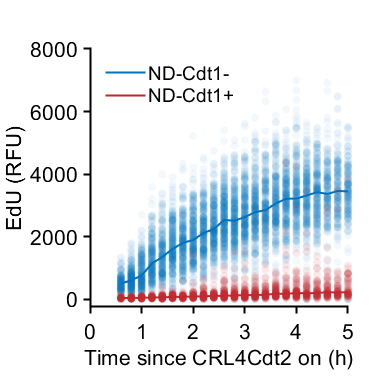

figure(f1)
legend(h,{'ND-Cdt1-', 'ND-Cdt1+'},'Location','northwest');
legend boxoff
axis square
% set(gca,'FontSize',16)
print_pdf([pwd() '\Figs\edu.pdf'])

**compare dna**

% gateVals = {{},{'FarRed1'}};
% rangeVals = {{[]},{[2^10 2^11]}};
%
% conds=[1 5*ones(1,length(gateVals)-1)];
% colors = [0 113 188; 193 39 45]/255;

poiAligned=3;
f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);
hold on

colorval = [1 2];
pattern = {'-','-'};
subsamplecells = [5500 2000];
% range = 0:1/framesPerHr:7;
alphas = [.05 .1];

for i=1:length(conds)
    ind=~isnan(S(conds(i)).POI(:,poiAligned))& ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i}) & S(conds(i)).POI_time(:,poiAligned) <=5;
    
    xdata = S(conds(i)).POI_time(ind,poiAligned) ;
    ydata = [];
    ydata(:, 1) = (S(conds(i)).dna(ind))/gate.dna_G1(1);
    ydata(:, 2) = (S(conds(i)).YFP2(ind));
    ydata(:, 3) = (S(conds(i)).FarRed2(ind) - gate.FarRed2_G1(1)) ;
    
    inds = ydata(:,1) > .9 & ydata(:,1) < 1.8;
    xdata = xdata(inds);
    ydata = ydata(inds);
    
    range = [unique(xdata); Inf];
    threshs ={{(gate.dna_G1(2)), -1}, {(gate.YFP2_G1(2)), 1}, {(gate.FarRed2_G1(2)), 1}};
    [binData, edges] = bin_xy(xdata, ydata, {'mean','median','perc'},...
        'Threshs',threshs, 'Edges',range);
    edges = edges(1:end-1);
    %     midpoints = edges + (edges(2) -edges(1))/2;
    midpoints = edges;
    cells = length(xdata)
    
    inds = randsample(cells,subsamplecells(i));
    xdata = xdata(inds);
    ydata = ydata(inds,:);
    
    figure(f1)
    hold on
    scatter(xdata,ydata(:, 1),'filled','MarkerFaceColor',colors(colorval(i),:),'MarkerFaceAlpha',alphas(i));
    %     h(i) = errorbar(midpoints, binData(3).mean, 2*binData(3).sem,'LineWidth',1.5,'Color',colors(colorval(i),:),'LineStyle',pattern{i});
    h(i) =  plot(midpoints, binData(1).median,'LineWidth',1.5,'Color',colors(colorval(i),:),'LineStyle',pattern{i});
    xlabel('Time since CRL4Cdt2 on (h)');
    ylabel('DNA content (Norm. to 2N)');
    xlim([0 5]);
    xticks([0:5])
    
    %     ylim([-500 7000])
    hline(gate.dna_G1(2)/gate.dna_G1(1),'k--');
    
end

cells = 5615

cells = 9393

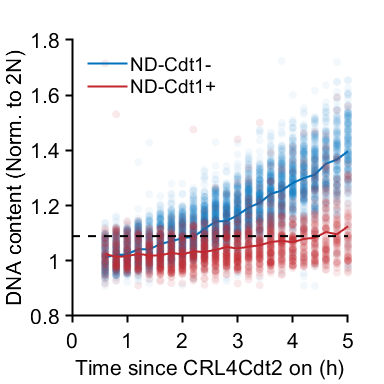

figure(f1)
legend(h,{'ND-Cdt1-', 'ND-Cdt1+'},'Location','northwest');
legend boxoff
axis square

% set(gca,'FontSize',16)
print_pdf([pwd() '\Figs\dna.pdf'])

**Dose response Cdt1 2-3 hrs**

rng(1)
conds=[5 6];
poiAligned=3;

range = 3.5:.25:14;
scale = endo_thresh;
range = range - 0;
% range = -5:.25:4.25;
timeGate = [2 3];

f1 = figure('Units', 'Inches', 'Position', [0, 0, 4, 4]);

cols = lines(length(conds));

gateVals = {{'FarRed1'}, {'FarRed1'}};
rangeVals = {{[gate.FarRed1_S(1) 2^14]},{[gate.FarRed1_S(1) 2^14]}};
a = [];

for i=1:length(conds)
    %%%%% get fit stuff
    ind= S(conds(i)).POI_time(:,poiAligned) >= timeGate(1) & S(conds(i)).POI_time(:,poiAligned) <= timeGate(2) & ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i}) & ...
        S(conds(i)).FarRed1 < gate.FarRed1_S(2) & S(conds(i)).FarRed1 > gate.FarRed1_S(1);    
    ydata=(S(conds(i)).FarRed2(ind) - gate.FarRed2_G1(1)) ;
    top_edu = mean(ydata);
    
    
    %%%%%% Get data
    ind= S(conds(i)).POI_time(:,poiAligned) >= timeGate(1) & S(conds(i)).POI_time(:,poiAligned) <= timeGate(2) & ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i});
    
    gatedata=real(log2(S(conds(i)).FarRed1(ind))) - 0;
    ydata=(S(conds(i)).FarRed2(ind) - gate.FarRed2_G1(1)) ;
    wells = string(num2str(S(conds(i)).wellindex(ind,1:2)));
    
%     keep = downsample_bins(gatedata,range);
%     gatedata = gatedata(keep);
%     ydata = ydata(keep);
%     wells = wells(keep);
    
    [binData, edges] = bin_xy(gatedata, ydata, {'mean','median'},...
        'Edges',range,'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
    edges = edges(1:end-1);
    midpoints = edges + (edges(2) -edges(1))/2;
    
    if i==1
        save_gate = gatedata;
    end
    
    %% Get fit
    minResponse=prctile(binData.g_ydata,5);
    midResponse=median(midpoints(binData.xInd));
    minDose=min(midpoints(binData.xInd));
    maxDose=max(midpoints(binData.xInd));
    
    sigmoid=@(beta,x)top_edu -(top_edu-beta(1))./(1+(2.^(x - beta(2))).^beta(3));
    coeffs = fitSigmoid(gatedata,ydata,sigmoid,[minResponse midResponse 1]);
    %     coeffBoot = bootstrp(1000,@(x,y) fitSigmoid(x,y,sigmoid,[minResponse midResponse 1]), midpoints(binData.xInd),binData.g_ydata,'Options',statset('UseParallel',true));
    %     coeffFilt = coeffBoot(coeffBoot(:,1) > 0,:);
    suppression_theory = top_edu/coeffs(1)
    suppression_max= top_edu/sigmoid(coeffs,maxDose)
    suppresion_endo = top_edu/sigmoid(coeffs,scale - scale)
    suppresion_endomax = top_edu/sigmoid(coeffs,endo_thresh - scale)
    coeffs
    %     suppression_boot = top_edu./coeffFilt(:,1);
    %     supp_int = prctile(suppression_boot,[2.5 97.5])

    
    %% Plot
    figure(f1)
    hold on
    errorbar(midpoints, binData.mean(:), 2*binData.sem(:),'o','LineWidth',1.5,'MarkerSize',5,'Color',cols(i,:),'MarkerFaceColor','w')
    xpoints = linspace(min(gatedata),max(midpoints),1000);
    a(i) = plot(xpoints,(sigmoid(coeffs,xpoints)),'Color',cols(i,:),'LineWidth',1.5);
    plot([coeffs(2) coeffs(2)],[6 (sigmoid(coeffs,coeffs(2)))] ,':','Color',cols(i,:),'LineWidth',2)
    scatter(coeffs(2),(sigmoid(coeffs,coeffs(2))),50,'o','MarkerEdgeColor',[0 0 0],'LineWidth',1.5)
    num_cells= binData.numCells(6:36)
    min_bin = min(binData.numCells(6:36))
    total_cells = length(ydata)
end

suppression_theory = 21.9938

suppression_max = 21.8999

suppresion_endo = 1.0000

suppresion_endomax = 1.0000

coeffs =    99.8368   10.2163   -4.2143


num_cells =    497   541   427   413   382   308   328   303   329   252   301   310   277   293   285   311   297   292   314   347   374   403   433   470   509   623   598   481   424   382   240


min_bin = 240

total_cells = 12039

suppression_theory = 23.0012

suppression_max = 22.6436

suppresion_endo = 1.0001

suppresion_endomax = 1.0001

coeffs =    87.9294    7.6534   -1.8252


num_cells =    146   153   136   116   117    75    96   102    91    92   111   110   104   112   142   121   131   130   139   143   130   153   142   164   185   201   234   235   225   201   141


min_bin = 75

total_cells = 4573

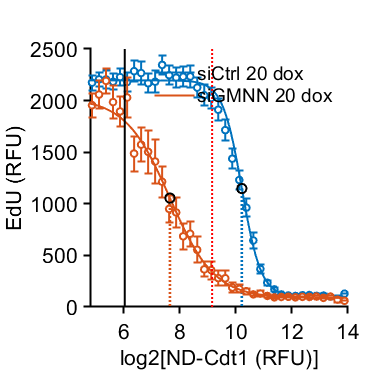

xlabel('log2[ND-Cdt1 (RFU)]');
ylabel('EdU (RFU)');

x1 = xlim;
xlim([x1(1) 14])
ylim([0 2500])
vline(log2(gate.FarRed1_S(2)) - 0,'k');
vline(endo_thresh - 0)
set(gca,'FontSize',16, 'LineWidth',1.5)
axis square
legend(a,conditions(conds, 1),'location','northeast');
legend('boxoff')

print_pdf([pwd() '\Figs\cdt1_dose_response_sem_2_3.pdf'])

vals = get(gca,'Position');
figure('units','inches','pos',[0 0 4 2]);
histogram(save_gate,range,'LineWidth',1.5)

xlim([x1(1) 14])
% set(gca,'YScale','log')
% ylim([0 250])
vline(log2(gate.FarRed1_S(2)) - 0,'k');
vline(endo_thresh - 0)
new_vals = get(gca,'Position');
set(gca,'Position',vals)
xlabel('log2[ND-Cdt1 (RFU)]');
box off
length(save_gate)

ans = 12039

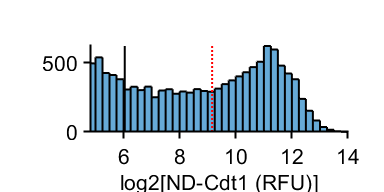

pbaspect([3 1 1])
print_pdf([pwd() '\Figs\cdt1_dose_response_binhist_2_3.pdf'])

**Geminin**

conds=[5 8 7 6];
poiAligned=3;

timeGate = [2 3];

gateVals = {{'FarRed1'}, {'FarRed1'},{'FarRed1'},{'FarRed1'}};
rangeVals = {{[gate.FarRed1_S(1) 2^13]},{[gate.FarRed1_S(1) 2^13]},{[gate.FarRed1_S(1) 2^13]},{[gate.FarRed1_S(1) 2^13]}};

data = {};

    
for i=1:length(conds)
    ind= S(conds(i)).POI_time(:,poiAligned) >= timeGate(1) & S(conds(i)).POI_time(:,poiAligned) <= timeGate(2) & ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i});
    
    gmnn = (S(conds(i)).YFP2(ind));
    gmnn(gmnn<8) = []; %cutting out small low percentage for plotting
    gmnn = log2(gmnn)';
    data = [data {gmnn}];
%     histogram(gmnn,'normalization','pdf')
end

cond = 5;
ind = isnan(S(cond).POI(:,2)) & isnan(S(cond).POI(:,3)) & ...
        S(cond).dna < 2^22 & S(cond).dna > 2^21 & S(cond).FarRed2 < 2^6;
gmnn = (S(cond).YFP2(ind));
    gmnn(gmnn<8) = []; %cutting out small low percentage for plotting
    gmnn = log2(gmnn)';
    data = [data {gmnn}];    
    
    
% alldata = cell2mat(data);
figure('Units', 'Inches', 'Position', [0, 0, 4, 2])
% cols = cmocean('ice',6);
% cols = cols(1:5,:);
colormap(lines(5))
nhist([data],'samebins','pdf','noerror','linewidth',1.5,'f',1,'color','colormap','xlabel','log2[GMNN (RFU)]','median','legend',{'siCtrl 20 nM','siGMNN 0.1 nM','siGMNN 1 nM','siGMNN 20 nM','G1 levels'},'FontSize',16)

ans = 1×5 cell array
    {'siCtrl 20 nM: median=8.75, '}    {'siGMNN 0.1 nM: median=6.98, '}    {'siGMNN 1 nM: median=6.54, '}    {'siGMNN 20 nM: median=6.07, 1 points counted in the rightmost bin are greater than 10.20 , '}    {'G1 levels: median=5.15, '}


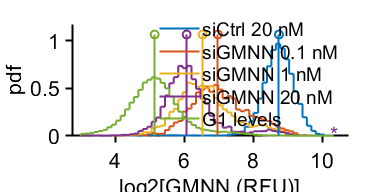

% axis square
xlim([2.75 10.75])
pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\gemindhists.pdf'])


data

data = 1×5 cell array
    {1×11979 double}    {1×4815 double}    {1×8673 double}    {1×4527 double}    {1×60673 double}


**Pool data**

conds=[5 6 7 8];
poiAligned=3;

timeGate = [2 3];

gateVals = {{'FarRed1'}, {'FarRed1'},{'FarRed1'},{'FarRed1'}};
rangeVals = {{[gate.FarRed1_S(1) 2^13]},{[gate.FarRed1_S(1) 2^13]},{[gate.FarRed1_S(1) 2^13]},{[gate.FarRed1_S(1) 2^13]}};
yTotal = [];
wellTotal = [];
gmnnTotal = [];
cdt1Total = [];

for i=1:length(conds)
    ind= S(conds(i)).POI_time(:,poiAligned) >= timeGate(1) & S(conds(i)).POI_time(:,poiAligned) <= timeGate(2) & ...
        gate_vals(S(conds(i)), gateVals{i}, rangeVals{i});
    cdt1 = S(conds(i)).FarRed1(ind);
    gmnn = S(conds(i)).YFP2(ind);
    ydata=(S(conds(i)).FarRed2(ind) - gate.FarRed2_G1(1)) ;
    wells = string(num2str(S(conds(i)).wellindex(ind,1:2)));
    
    yTotal = [yTotal; ydata];
    wellTotal = [wellTotal; wells];
    gmnnTotal = [gmnnTotal; gmnn];
    cdt1Total = [cdt1Total; cdt1];
end


**Dose response gating for geminin levels**

Set gates

cdt1_range = 3.5:.5:13;
cdt1_range = cdt1_range - 0;
% cdt1_range = prctile(log2(cdt1Total),[0:2:99]);
% cdt1_range = linspace(min(log2(cdt1Total)),13,50);
edges = cdt1_range(1:end-1);
midpoints = edges + (edges(2) -edges(1))/2;
% gem_range = 2.^linspace(4, 9, 20);
gmnnFilt = gmnnTotal(gmnnTotal > gate.YFP2_G1(1));
lower_bound = log2(min(gmnnFilt));
upper_bound = log2(prctile(gmnnFilt,99));
gem_range = 2.^linspace(lower_bound, upper_bound,13);


get fit stuff (max edu)

ind= cdt1Total > 2^4 & cdt1Total < 2^6 & gmnnTotal > 100  & gmnnTotal < 400;
gatedata=cdt1Total(ind);
ydata=yTotal(ind);
wells = wellTotal(ind);

% [binCtrl, ~] = bin_xy(gatedata, ydata, {'mean','median'},...
%     'Edges',[-Inf Inf],'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
% top_edu = binCtrl.g_mean;
top_edu = mean(ydata);

ind= cdt1Total > 2^12;
gatedata=cdt1Total(ind);
ydata=yTotal(ind);
wells = wellTotal(ind);

% [binCtrl, ~] = bin_xy(gatedata, ydata, {'mean','median'},...
%     'Edges',[-Inf Inf],'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
% bot_edu = binCtrl.g_mean;
bot_edu = mean(ydata);


Get and plot fits

f1 = figure('units','inches','pos',[0 0 4 4]);
f2 = figure('units','inches','pos',[0 0 2*(length(gem_range)-1)/3 2*3]);
% cols = winter(length(gem_range)-1);
% cols = viridis(length(gem_range)-1+2);
% cols = copper(length(gem_range)-1+2);
% cols = cividis(length(gem_range)-1);
% cols = cbrewer('seq','YlGnBu',length(gem_range)-1+6);
% cols = cols(6:end,:);
cols = cmocean('ice',length(gem_range)-1+2);
scale = 0;
gateVals = {};
rangeVals = {[]};

allGemMeans = NaN*ones(1,length(gem_range)-1);
allIC50 =  NaN*ones(1,length(gem_range)-1);
allHC =  NaN*ones(1,length(gem_range)-1);

allmap = NaN*ones(length(gem_range)-1,length(cdt1_range)-1);

mins = [];
bins =[];
for i=1:length(gem_range)-1
    ind= gmnnTotal > gem_range(i) & gmnnTotal < gem_range(i+1) & cdt1Total > 1;
    
    gatedata=log2(cdt1Total(ind)) - scale;
    ydata=yTotal(ind);
    wells = wellTotal(ind);
    gem_mean = mean(gmnnTotal(ind));
    
    [binData, ~] = bin_xy(gatedata, ydata, {'mean','median'},...
        'Edges',cdt1_range,'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
    
    if length(gatedata)> 20
        %%%%%% Get fit
        %    minResponse=prctile(binData.g_ydata,5);
        midResponse=nanmedian(gatedata);
        minDose=min(midpoints(binData.xInd));
        maxDose=max(midpoints(binData.xInd));
        
        sigmoid=@(beta,x)top_edu-(top_edu-bot_edu)./(1+(2.^( beta(1) - x)).^beta(2));
        %         coeffs = fitSigmoid(midpoints(binData.xInd),binData.g_ydata,sigmoid,[midResponse 1]);
        coeffs = fitSigmoid(gatedata,ydata,sigmoid,[midResponse 1]);
        %     coeffBoot = bootstrp(1000,@(x,y) fitSigmoid(x,y,sigmoid,[midResponse 1]), midpoints(binData.xInd),binData.g_ydata,'Options',statset('UseParallel',true));
        %     coeffFilt = coeffBoot(coeffBoot(:,1) > 0,:);
        %     suppression_theory = top_edu/coeffs(1)
        %     suppression_max= top_edu/sigmoid(coeffs,maxDose)
        coeffs;
        %     suppression_boot = top_edu./coeffFilt(:,1);
        %     supp_int = prctile(suppression_boot,[2.5 97.5])
        %     [C,ia,ic] = unique(binData.xInd);
        %     a_counts = accumarray(ic,1)
        
        allGemMeans(i) = gem_mean;
        allIC50(i) = coeffs(1);
        allHC(i) = coeffs(2);
        allmap(i,:) = binData.mean;
        
        %%%%%%%% Plot ind curves
        figure(f2)
        subplot(3,ceil((length(gem_range)-1)/3),i)
        hold on
        %         scatter(gatedata,ydata,25,'o','MarkerEdgeColor','k','MarkerEdgeAlpha',.5,'LineWidth',1.5);
        %             errorbar(midpoints, binData.g_mean(:), 2*binData.g_sem(:),'o','LineWidth',1.5,'MarkerSize',6,'Color',cols(i,:),'MarkerFaceColor','w')
        errorbar(midpoints, binData.mean(:), 2*binData.sem(:),'o','LineWidth',1,'MarkerSize',3,'Color',cols(i,:),'MarkerFaceColor','w')
        %             scatter(midpoints(binData.xInd),binData.g_ydata,25,'o','MarkerEdgeColor',cols(i,:),'MarkerEdgeAlpha',.5,'LineWidth',1.5);
        xpoints = linspace(min(midpoints),max(midpoints),1000);
        a(i) = plot(xpoints,(sigmoid(coeffs,xpoints)),'Color',cols(i,:),'LineWidth',1.5);
        plot([coeffs(1) coeffs(1)],[6 (sigmoid(coeffs,coeffs(1)))] ,':','Color',[0 0 0],'LineWidth',1.5)
        scatter(coeffs(1),(sigmoid(coeffs,coeffs(1))),50,'o','MarkerEdgeColor',[0 0 0 ],'LineWidth',1)
        
        xlabel('log2[ND-Cdt1 (RFU)]');
        ylabel('EdU (RFU)');
        x1 = xlim;
        xlim([x1(1) 13])
        ylim([0 3500])
        vline(log2(gate.FarRed1_S(1)) - scale,'k');
        vline(endo_thresh)
        set(gca,'FontSize',8, 'LineWidth',1.5)
        axis square
        title({'Mean Geminin:',sprintf('%.1f RFU',gem_mean)},'Color',cols(i,:))
        
        
        %%%%%%% plot combined curve plot
        figure(f1)
        hold on
        xpoints = linspace(min(midpoints),max(midpoints),1000);
        a(i) = plot(xpoints,(sigmoid(coeffs,xpoints)),'Color',cols(i,:),'LineWidth',1.5);
        scatter(coeffs(1),(sigmoid(coeffs,coeffs(1))),50,'o','MarkerEdgeColor',cols(i,:),'LineWidth',1.5)
        plot([coeffs(1) coeffs(1)],[6 (sigmoid(coeffs,coeffs(1)))] ,':','Color',cols(i,:),'LineWidth',1.5)
    
%         mins = [mins min(binData.numCells(binData.numCells > 0))];
        bins = [bins (binData.numCells(binData.numCells > 0)) ];
    end
end
min(bins)

ans = 6

median(bins)

ans = 127

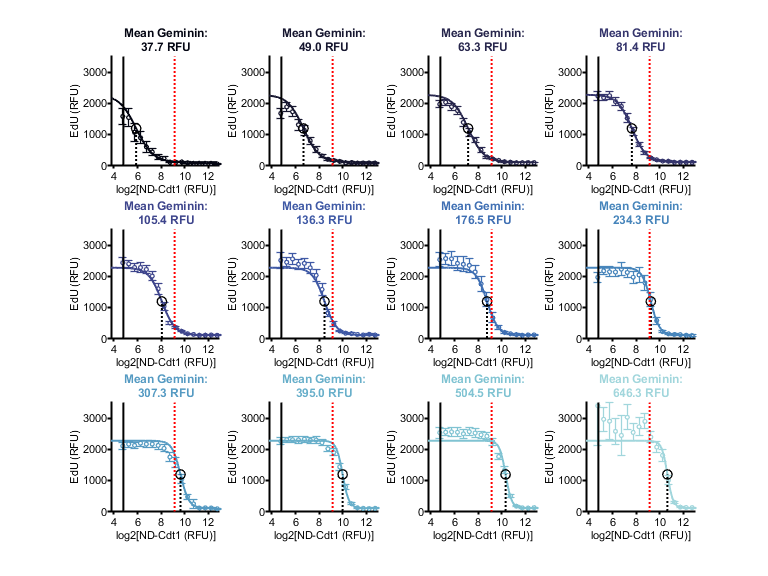

figure(f2)
print_pdf([pwd() '\Figs\gemgate_ind.pdf'])

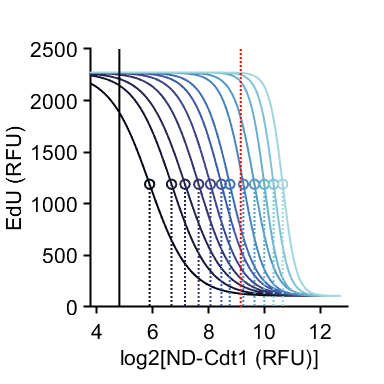


%%%%%%% plot combined curve plot
figure(f1)
xlabel('log2[ND-Cdt1 (RFU)]');
ylabel('EdU (RFU)');
x1 = xlim;
xlim([x1(1) 13])
ylim([0 2500])
vline(log2(gate.FarRed1_S(1)) - scale,'k');
vline(endo_thresh)
set(gca,'FontSize',16, 'LineWidth',1.5)
axis square
print_pdf([pwd() '\Figs\cdt1_dose_response_gemgate.pdf'])

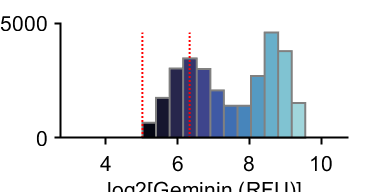


%%%% plot gate histogram
figure('units','inches','pos',[0 0 4 2])
N = histcounts(real(log2(gmnnTotal)),log2(gem_range));
hold on
for i = 1:size(allmap,1)
    xmin = log2(gem_range(i));
    xmax = log2(gem_range(i+1));
    fill([xmin xmax xmax xmin],[0 0 N(i) N(i)],cols(i,:),'LineWidth',1.5,'EdgeColor',[.5 .5 .5])
end
xlabel('log2[Geminin (RFU)]')
set(gca, 'Layer','Top')
xlim([log2(min(gem_range))-1  log2(max(gem_range))+1])
vline(log2(gate.YFP2_G1))

xlim([2.75 10.75])
pbaspect([2.5 1 1])
print_pdf([pwd() '\Figs\gemgate_hist.pdf'])


%%%% plot scatters
figure('units','inches','pos',[0 0 4 4]), hold on
p = polyfit(allGemMeans,2.^allIC50,1);
xvals = [0 800];
pval = polyval(p,xvals);
fitlm(allGemMeans,2.^allIC50)

ans = Linear regression model:
    y ~ 1 + x1

Estimated Coefficients:
                   Estimate       SE        tStat       pValue  
                   ________    ________    _______    __________

    (Intercept)    -10.816       8.6038    -1.2571       0.23728
    x1              2.5684     0.029047      88.42    8.3762e-16


Number of observations: 12, Error degrees of freedom: 10
Root Mean Squared Error: 19
R-squared: 0.999,  Adjusted R-Squared: 0.999
F-statistic vs. constant model: 7.82e+03, p-value = 8.38e-16

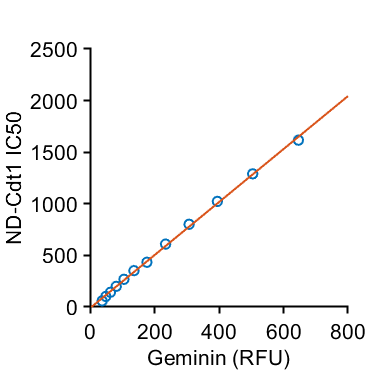

scatter(allGemMeans,2.^allIC50,50,'LineWidth',1.5)
plot(xvals,pval,'LineWidth',1.5);
ylim([0 2500])
% hline(1,'k--')
% gem_val = (1 - p(2))/p(1)
% vline(gem_val,'k--')
xlabel('Geminin (RFU)')
ylabel('ND-Cdt1 IC50')
axis square

print_pdf([pwd() '\Figs\gemgate_IC50.pdf'])

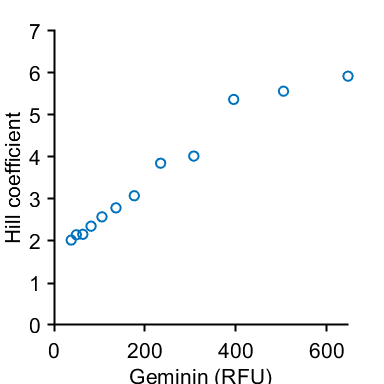



figure('units','inches','pos',[0 0 4 4])
scatter(allGemMeans,allHC,50,'LineWidth',1.5)
ylim([0 7])
axis square
xlabel('Geminin (RFU)')
ylabel('Hill coefficient')
print_pdf([pwd() '\Figs\gemgate_HC.pdf'])

Plot 3D map log

% cdt1_range = 3.5:.25:13;
% cdt1_range = prctile(log2(cdt1Total),[0:2:99]);
scale = endo_thresh;
cdt1_range = linspace(min(log2(cdt1Total)),13,50) - 0;
edges = cdt1_range(1:end-1);
midpoints = edges + (edges(2) -edges(1))/2;
% gem_range = linspace(50, 550, 20);
gmnnFilt = gmnnTotal(gmnnTotal > gate.YFP2_G1(1));
gem_range = prctile(gmnnFilt,[0:5:99]);
lower_bound = log2(min(gmnnFilt));
upper_bound = log2(prctile(gmnnFilt,99));
gem_range = 2.^linspace(lower_bound, upper_bound,13);

f1 = figure('units','inches','pos',[0 0 4 4]);
f2 = figure('units','inches','pos',[0 0 2*(length(gem_range)-1)/3 2*3]);
cols = winter(length(gem_range)-1);
% cols = viridis(length(gem_range)-1);

%%%%% get fit stuff
ind= cdt1Total > 2^4 & cdt1Total < 2^6 & gmnnTotal > 200  & gmnnTotal < 400;
gatedata=cdt1Total(ind);
ydata=yTotal(ind);
wells = wellTotal(ind);

% [binCtrl, ~] = bin_xy(gatedata, ydata, {'mean','median'},...
%     'Edges',[-Inf Inf],'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
% top_edu = binCtrl.g_mean;
top_edu = mean(ydata);

ind= cdt1Total > 2^12;
gatedata=cdt1Total(ind);
ydata=yTotal(ind);
wells = wellTotal(ind);

% [binCtrl, ~] = bin_xy(gatedata, ydata, {'mean','median'},...
%     'Edges',[-Inf Inf],'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
% bot_edu = binCtrl.g_mean;
bot_edu = mean(ydata);

gateVals = {};
rangeVals = {[]};

allGemMeans = NaN*ones(1,length(gem_range)-1);
allIC50 =  NaN*ones(1,length(gem_range)-1);
allHC =  NaN*ones(1,length(gem_range)-1);

allmap = NaN*ones(length(gem_range)-1,length(cdt1_range)-1);

numCells = [];
for i=1:length(gem_range)-1
    ind= gmnnTotal > gem_range(i) & gmnnTotal < gem_range(i+1) & cdt1Total > 1;
    
    gatedata=log2(cdt1Total(ind)) - 0;
    ydata=yTotal(ind);
    wells = wellTotal(ind);
    gem_mean = mean(gmnnTotal(ind));
    
    [binData, ~] = bin_xy(gatedata, ydata, {'mean','median'},...
        'Edges',cdt1_range,'Groups',wells,'MinGroupBin',5,'GroupFunc',@nanmedian);
    
    
    numCells(i) = length(ydata);
    if length(gatedata)> 20
        %% Get fit
        %    minResponse=prctile(binData.g_ydata,5);
        midResponse=median(gatedata);
        minDose=min(midpoints(binData.xInd));
        maxDose=max(midpoints(binData.xInd));
        
        sigmoid=@(beta,x)bot_edu+(top_edu-bot_edu)./(1+(2.^(x - beta(1))).^beta(2));
        %         coeffs = fitSigmoid(midpoints(binData.xInd),binData.g_ydata,sigmoid,[midResponse 1]);
        coeffs = fitSigmoid(gatedata,ydata,sigmoid,[midResponse 1]);
        %     coeffBoot = bootstrp(1000,@(x,y) fitSigmoid(x,y,sigmoid,[midResponse 1]), midpoints(binData.xInd),binData.g_ydata,'Options',statset('UseParallel',true));
        %     coeffFilt = coeffBoot(coeffBoot(:,1) > 0,:);
        %     suppression_theory = top_edu/coeffs(1)
        %     suppression_max= top_edu/sigmoid(coeffs,maxDose)
        coeffs;
        %     suppression_boot = top_edu./coeffFilt(:,1);
        %     supp_int = prctile(suppression_boot,[2.5 97.5])
        %     [C,ia,ic] = unique(binData.xInd);
        %     a_counts = accumarray(ic,1)
        
        allGemMeans(i) = gem_mean;
        allIC50(i) = coeffs(1);
        allHC(i) = coeffs(2);
        allmap(i,:) = binData.mean;
        
        %         %% Plot
        %         figure(f2)
        %         subplot(3,ceil((length(gem_range)-1)/3),i)
        %         hold on
        % %         scatter(gatedata,ydata,25,'o','MarkerEdgeColor','k','MarkerEdgeAlpha',.5,'LineWidth',1.5);
        % %             errorbar(midpoints, binData.g_mean(:), 2*binData.g_sem(:),'o','LineWidth',1.5,'MarkerSize',6,'Color',cols(i,:),'MarkerFaceColor','w')
        %             errorbar(midpoints, binData.mean(:), 2*binData.sem(:),'o','LineWidth',1,'MarkerSize',3,'Color',cols(i,:),'MarkerFaceColor','w')
        % %             scatter(midpoints(binData.xInd),binData.g_ydata,25,'o','MarkerEdgeColor',cols(i,:),'MarkerEdgeAlpha',.5,'LineWidth',1.5);
        %         xpoints = linspace(min(midpoints),max(midpoints),1000);
        %         a(i) = plot(xpoints,(sigmoid(coeffs,xpoints)),'Color',cols(i,:),'LineWidth',1.5);
        %         scatter(coeffs(1),(sigmoid(coeffs,coeffs(1))),200,'x','MarkerEdgeColor',cols(i,:),'LineWidth',1)
        %         plot([coeffs(1) coeffs(1)],[6 (sigmoid(coeffs,coeffs(1)))] ,':','Color',cols(i,:),'LineWidth',2)
        %         xlabel('log2(Cdt1)');
        %         ylabel('Mean EdU');
        %         xlim([3 13])
        %         ylim([0 3000])
        %         vline(log2(gate.FarRed1_S(1)),'k');
        %         set(gca,'FontSize',8, 'LineWidth',1.5)
        %         axis square
        %         title(sprintf('Mean Geminin: %.1f',gem_mean))
        %
        %         figure(f1)
        %         hold on
        %         xpoints = linspace(min(midpoints),max(midpoints),1000);
        %         a(i) = plot(xpoints,(sigmoid(coeffs,xpoints)),'Color',cols(i,:),'LineWidth',1.5);
        %         scatter(coeffs(1),(sigmoid(coeffs,coeffs(1))),50,'o','MarkerEdgeColor',cols(i,:),'LineWidth',1.5)
        %         plot([coeffs(1) coeffs(1)],[6 (sigmoid(coeffs,coeffs(1)))] ,':','Color',cols(i,:),'LineWidth',2)
    end
end
sum(numCells)

ans = 29350

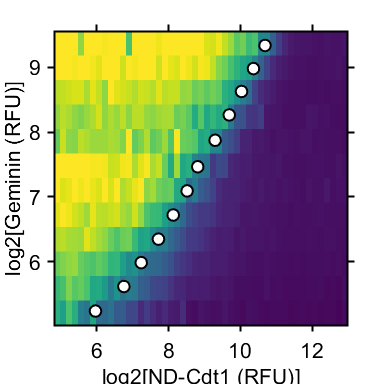

% xlabel('log2(Cdt1)');
% ylabel('Mean EdU');
% xlim([3 13])
% ylim([0 3000])
% vline(log2(gate.FarRed1_S(1)),'k');
% set(gca,'FontSize',16, 'LineWidth',1.5)
% axis square
% % legend(a,conditions(conds, 1));
% % legend('boxoff')

% print_pdf([pwd() '\Figs\cdt1_dose_response_sem.pdf'])

figure('units','inches','pos',[0 0 4 4]), hold on
colormap('viridis')
for i = 1:size(allmap,1)
    ymin = log2(gem_range(i));
    ymax = log2(gem_range(i+1));
    for j = 1:size(allmap,2)
        xmin = cdt1_range(j);
        xmax = cdt1_range(j+1);
        fill([xmin xmin xmax xmax],[ymin ymax ymax ymin],allmap(i,j),'LineStyle','none')
    end
end
scatter(allIC50, log2(allGemMeans),75,'o','filled','MarkerEdgeColor','k','MarkerFaceColor','w','LineWidth',1.5)
caxis([0 2500])
% colormap(viridis);
xlim([cdt1_range(1) 13])
ylim(log2(gem_range([1 end])))
xlabel('log2[ND-Cdt1 (RFU)]')
ylabel('log2[Geminin (RFU)]')
axis square
set(gca, 'Layer','Top')
box on
print_pdf([pwd() '\Figs\log_3d.pdf'])

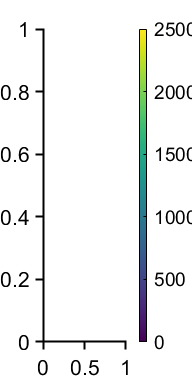


figure('units','inches','pos',[0 0 2 4]), hold on
colormap('viridis')

caxis([0 2500])
colorbar
print_pdf([pwd() '\Figs\edu_colormap.pdf'])


% figure('units','inches','pos',[0 0 4 4])
% a(1) =  subplot(2,1,1);
% hold on
% histogram(real(log2(gmnnTotal)),log2(gem_range),'normalization','pdf','LineWidth',1)
% a(2) = subplot(2,1,2);
% hold on
% for i = 1:size(allmap,1)
%     xmin = log2(gem_range(i));
%     xmax = log2(gem_range(i+1));
%     fill([xmin xmax xmax xmin],[0 0 10 10],cols(i,:),'LineWidth',1)
% end
% linkaxes(a,'x')

function coeffs = fitSigmoid(dose, response, func, init)
coeffs = nlinfit(dose,response,func,init,'ErrorModel','proportional');
end
